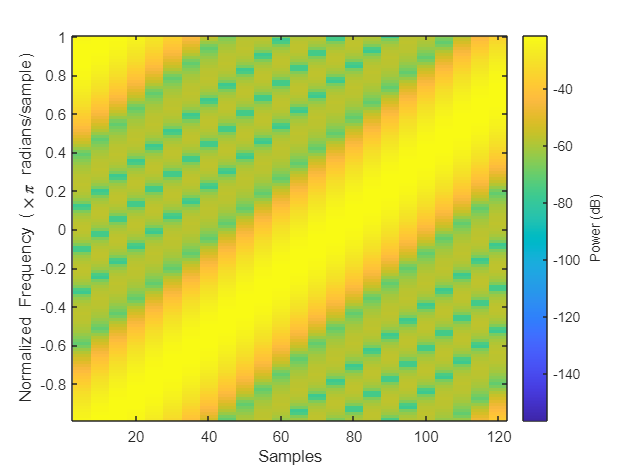

SF=7;
BW=125e3;
Fs=BW;
s=52;
SNR=-20;

%generate data symbol
num_samples = (2^SF)*Fs/BW;
k=s;
lora_symbol=zeros(1,num_samples);
for n=1:num_samples
    if k >= (2^SF)
        k=k-2^SF;
    end 
    k = k+1;
    lora_symbol(n)=(1/(sqrt(2^SF)))*exp(1i*2*pi*k*(k/((2^SF)*2)));
end


% Apply a window function to smooth out boundary transitions
window = blackman(num_samples).'; %  window
windowed_symbol = lora_symbol .* window;

spectrogram(lora_symbol,10,5,128,'power','centered', 'yaxis');

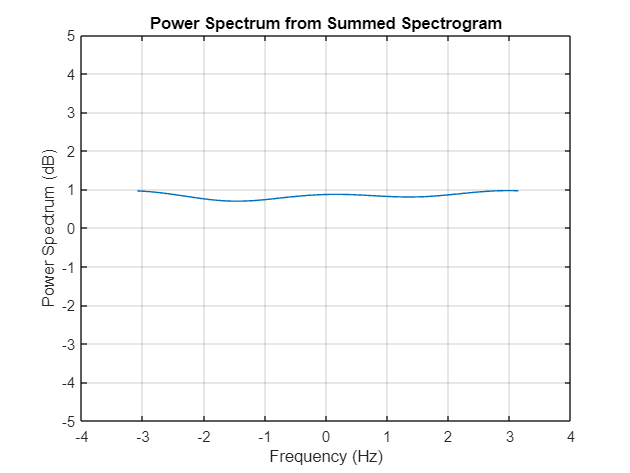

[pxx,f]=spectrogram(lora_symbol,4,2,128,'power','centered', 'yaxis');

power_spectrum = sum(pxx, 2);

% Convert power to dB
power_spectrum_db = 10 * log10(abs(power_spectrum));

% Plot the power spectrum
figure;
plot(f, abs(power_spectrum));
grid on;
title('Power Spectrum from Summed Spectrogram');
xlabel('Frequency (Hz)');
ylabel('Power Spectrum (dB)');
ylim([-5, 5]);

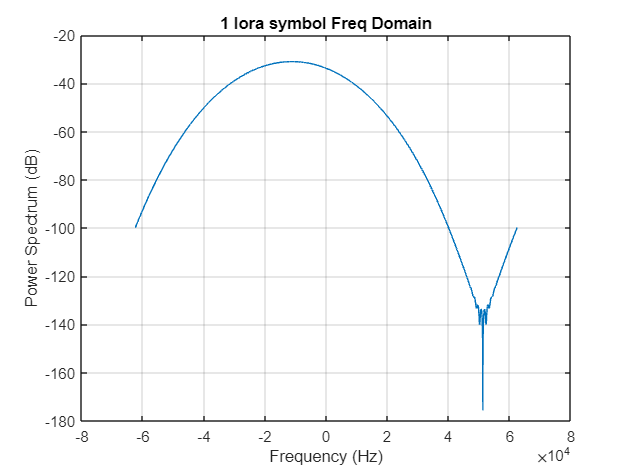


figure
[pxx,f] = pspectrum(lora_symbol,Fs);
plot(f,pow2db(pxx))
grid on
title('1 lora symbol Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

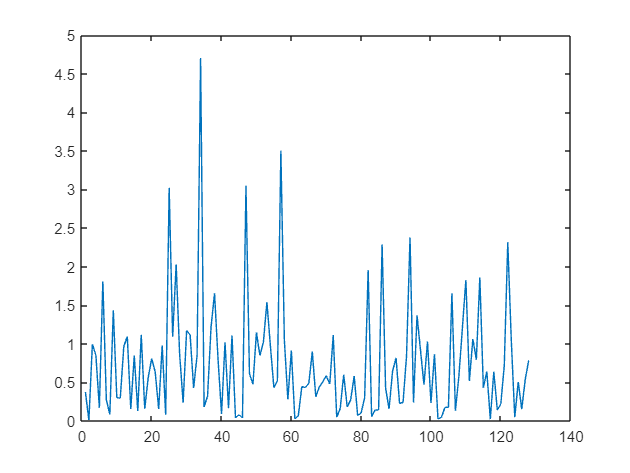


%add noise
for j = 1:500%100
    lora_symbol_noisy= awgn(lora_symbol,SNR,'measured');

    
    base_down_chirp=zeros(1,num_samples);
    k=0;
    for n=1:num_samples
        if k>= (2^SF)
            k=k-2^SF;
        end
        k=k+1;
        base_down_chirp(n)=(1/(sqrt(2^SF)))*exp(-1i*2*pi*k*(k/(2^SF*2)));
    end

    dechirped=lora_symbol_noisy.*base_down_chirp;
    corrs=(abs(fft(dechirped)).^2);
    plot(corrs)
    [~, ind]=max(corrs);
    ind2(j)=ind;
    pause(0.01)
end

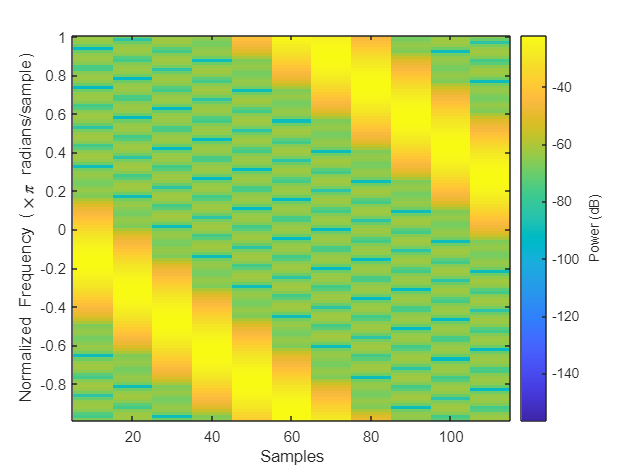


spectrogram(base_down_chirp,20,10,128,'power','centered', 'yaxis');

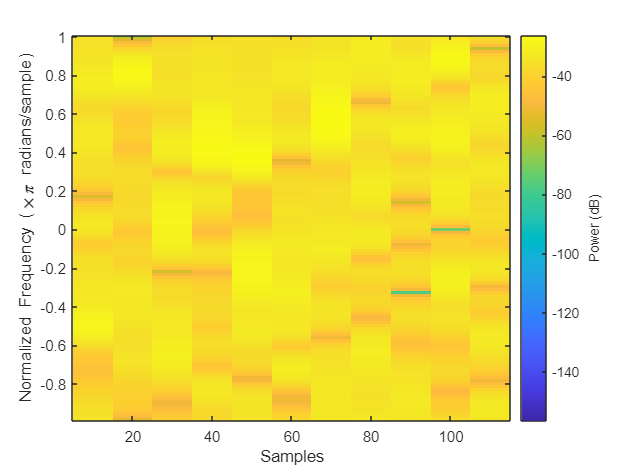

spectrogram(dechirped,20,10,128,'power','centered', 'yaxis');

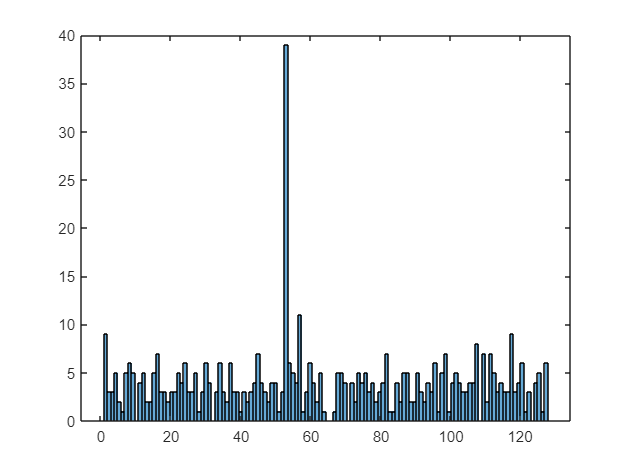


histogram(ind2,2^SF)

symbol_error_rate= sum(ind2~=s+1)/j

symbol_error_rate = 0.9220


spectrogram(lora_symbol_noisy,20,10,128,'power','centered', 'yaxis');
    